# **EEE-3102: Numerical Technique Laboratory**

# **Lab-03: Determination of model parameters using polynomial curve fitting technique.**

#### **Lab Group- B**

#### **Name: M. Ashikuzzaman Kowshik**

#### **Class roll: AE-073-051**

### **Q.1:** suppose x values are within the range of 0 <= *x <=* 10 and y = 2+3x. Determine the model parameters using the above Eq. (1) and Eq. (2). Note that, for example, ∑x is done by sum(x) and *x* = ∑(*x**i */ *n) * is done by mean(x) in Matlab.

####         (i) Paste your code below

#### **        (ii) What are the model parameters obtained by running your ****code?**

x = 0:0.5:10;
y0 = 2+3*x;
n = 21;
x_bar = mean(x)

x_bar = 5

y_bar = mean(y0)

y_bar = 17

a1 = (n*sum(x.*y0) - (sum(x)*sum(y0)))./(n*sum(x.^2)-(sum(x)).^2)

a1 = 3

a0 = y_bar - x_bar.*a1

a0 = 2

### Q.2: Comment on the curve you obtained after running the code in example-1. What is the value of mean square error (MSE)? Why MSE value is so small?

clc;close all;
x=0:0.5:10;
y0=2*x+3;               % let it gives observed values
n=1;                    % order used
a = polyfit(x,y0,n)       % gives model parameters

a =     2.0000    3.0000


ym = polyval(a,x)        % gives the fittd values

ym =     3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000   20.0000   21.0000   22.0000   23.0000


MSE = mean((y0-ym).^2)

MSE = 2.5168e-30

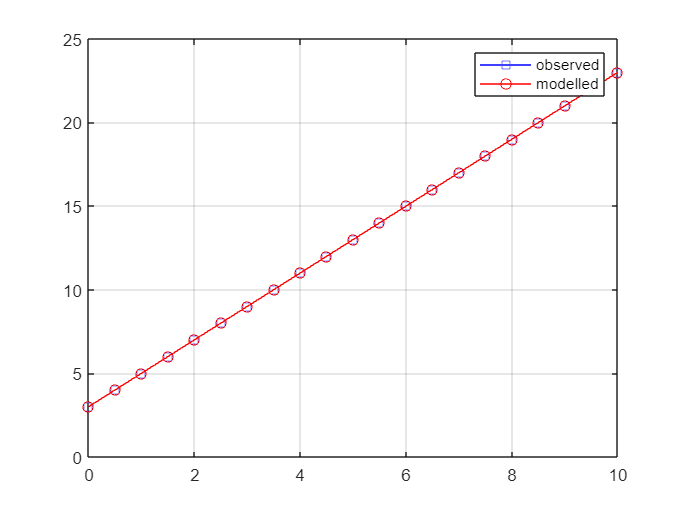


figure;
plot(x,y0,'-bs') 
hold on 
plot(x,ym,'-ro') 
grid on
legend('observed','modelled')


%comment:
%The value of MSE is 0 
%because there is no difference modeled and observed curve.

### Q.3: Given that that y = 2+3x for 0 $\le$ x $\le$ 10 is a polynomial equation (linear in this case). Produce y0 by adding noise to y such that the SNR = 20dB. Now use the same procedures of Example-1 to fit y0

####         (i) Plot the observed data yo and modeled data ym in the same plot and paste the plot below.

clc;close all;
x = 0:0.2:10;
y = 2+3*x;                  % given polynomial equation
n = 1;                      % order used
dB = 20;
y0 = awgn(y,dB,'measured');
a = polyfit(x,y0,n)         % gives model parameters

a =     3.1408    0.7882


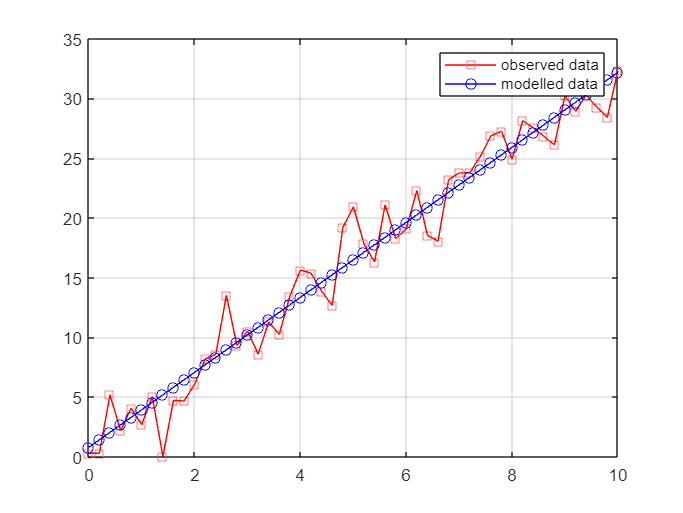

ym = polyval(a,x);          % gives the fitted values

figure;
plot(x,y0,'-rs')
hold on
plot(x,ym,'-bo')
grid on
legend('observed data','modelled data')

####         (ii) What are the model parameters now?

####         (iii) What is the value of MSE now?

clc;close all;
x = 0:0.2:10;
y = 2+3*x;      % given polynomial equation
n = 1;          % order used

dB = 20;
y0 = awgn(y,dB,'measured');
a = polyfit(x,y0,n); % gives model parameters
ym = polyval(a,x); % gives the fitted values
MSE = mean((y0-ym).^2) % gives mean square error

MSE = 3.6381

####         (iv) List the model parameters for SNR of 25, 30 and 35 dB and comment on the values of the parameters.

clc;close all;
x = 0:0.2:10;
y = 2+3*x;                      % given polynomial equation
n = 1;                          % order used


for dB = 20:5:35
    y0 = awgn(y,dB,'measured');
    a = polyfit(x,y0,n)         % gives model parameters
    
    ym = polyval(a,x);          % gives the fitted values
    MSE = mean((y0-ym).^2)      % gives mean square error
end

a =     2.9954    2.2268


MSE = 4.2024

a =     3.0165    2.1873


MSE = 1.2048

a =     3.0571    1.6540


MSE = 0.3936

a =     3.0051    2.0376


MSE = 0.1112

####         (v) Run the code for SNR from 20 to 30 dB with 1 dB step each time and store the MSE in an excel file. Draw a curve to show the plot of SNR (dB) versus MSE.

clc;close all;
x = 0:0.2:10;
y = 2+3*x;                      % given polynomial equation
n = 1;                          % order used
d = 20;
for i = 1:11
    y0 = awgn(y,d,'measured');
    a = polyfit(x,y0,n);        % gives model parameters
    ym = polyval(a,x);          % gives the fitted values
    c = mean((y0-ym).^2);       % gives mean square error
    MSE(i) = c;
    dB(i) = d;
    d = d+1;
end
data = [dB;MSE]

data =    20.0000   21.0000   22.0000   23.0000   24.0000   25.0000   26.0000   27.0000   28.0000   29.0000   30.0000
    3.8318    2.5189    1.6258    1.2323    1.7074    0.9367    1.1660    0.6374    0.4973    0.5060    0.3094


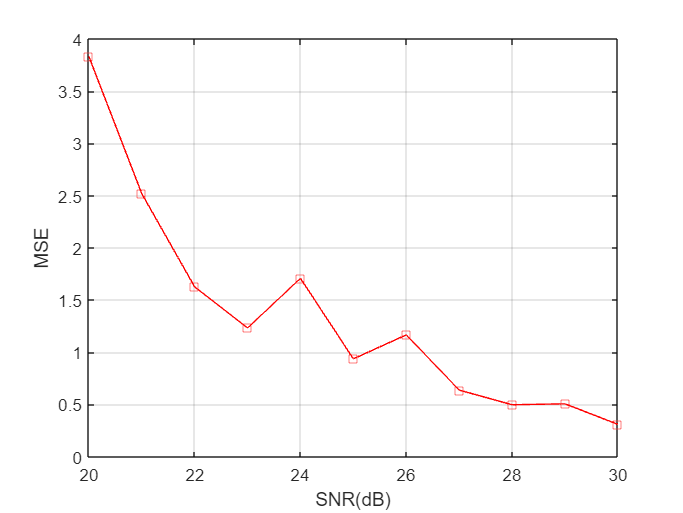


writematrix(data, "MSE.xlsx")
figure;
plot(dB,MSE,'-rs')
xlabel('SNR(dB)')
ylabel('MSE')
grid on

### Q.4: For 0 <= x <= 1 with an increment of 0.02, given that

*y *= 10*x^*10 + 9*x^*9+ 8*x^*8+ 7*x^*7+ 6*x^*6+ 5*x^*5+ 4*x^*4+ 3*x^*3+ 2*x^*2+ *x *+ 10

####         (i) fit the data y with 10th order ( n= 10) polynomial and find the model parameters and MSE. Comment on your results.

clc;close all;
x = 0:0.02:1;
y = 10*x.^10+9*x.^9+8*x.^8+7*x.^7+6*x.^6+5*x.^5+4*x.^4+3*x.^3+2*x.^2+x+10; 
% givenpolynomial equation
n = 10;                 % order used
a = polyfit(x,y,n)      % gives model parameters

a =    10.0000    9.0000    8.0000    7.0000    6.0000    5.0000    4.0000    3.0000    2.0000    1.0000   10.0000


ym = polyval(a,x);      % gives the fitted values
MSE = mean((y-ym).^2)   % gives mean square error

MSE = 1.4725e-29

####         (ii) Now, Produce yo by adding noise to y such that the SNR = 20dB. Now use the same procedures of Example-1 to fit yo. What is the value of MSE for n =1 (i.e., first order polynomial)?

clc;close all;
x = 0:0.02:1;
y = 10*x.^10+9*x.^9+8*x.^8+7*x.^7+6*x.^6+5*x.^5+4*x.^4+3*x.^3+2*x.^2+x+10; 
% given polynomial equation
n = 1;                      % order used
dB = 40;
y0 = awgn(y,dB,'measured');
a = polyfit(x,y0,n)         % gives model parameters

a =    34.9267    0.8767



ym = polyval(a,x);          % gives the fitted values
MSE = mean((y0-ym).^2)      % gives mean square error

MSE = 66.4980

####         (iii) Vary the order n of the polynomial from 1 to 10 and record your result in an excel file. Draw a plot to show a graph of order (n) versus MSE.

clc;close all;
x = 0:0.02:1;
y = 10*x.^10+9*x.^9+8*x.^8+7*x.^7+6*x.^6+5*x.^5+4*x.^4+3*x.^3+2*x.^2+x+10; 
% given polynomial equation
dB = 40;
y0 = awgn(y,dB,'measured');
for i = 1:1:10
    a = polyfit(x,y0,i);    % gives model parameters
    ym = polyval(a,x);      % gives the fitted values
    m = mean((y0-ym).^2);   % gives mean square error
    MSE(i) = m;
    n(i) = i;
end
data = [n;MSE]'

data =     1.0000   67.5752
    2.0000   17.0961
    3.0000    2.5624
    4.0000    0.2494
    5.0000    0.0514
    6.0000    0.0417
    7.0000    0.0402
    8.0000    0.0402
    9.0000    0.0400
   10.0000    0.0384


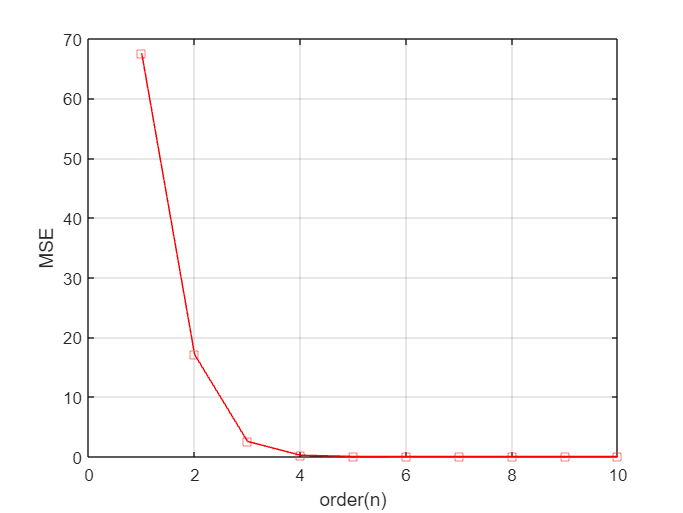


writematrix(data, "MSE1.xlsx")

figure;
plot(n,MSE,'-rs')
xlabel('order(n)')
ylabel('MSE')
grid on